**Thresholding Method Notebook**

**Kuan-Min Lee**

**Thresholding Method:**

**Basic Theory explanation:**

**Citation: Lecture Automatic Thresholding**

We can change the **pixels of an image** to make the image easier to analyze.

In thresholding, we convert an image **from color or grayscale into binary image. Most Frequently, we use thresholding as a way to select area of interest of an image and ignore the parts we are not concerned with:**

**Relative Function: **

**imbinarize(I,method) function\**

**Image citation: Zanaty, E.. (2016). Medical Image Segmentation Techniques: An Overview. International Journal of informatics and medical data processing (JIMDP). 1. 1. **

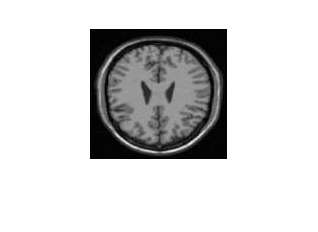

img=imread("original_brain_test_img.png"); % read in testing image for thresholding function
imshow(img)

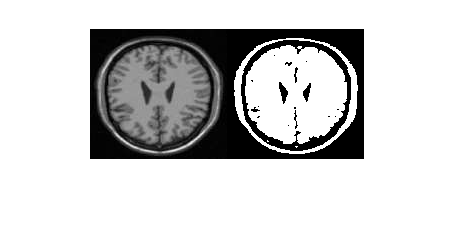

BW_img=imbinarize(img); % utilize the imbinarize function to get binarization version of the image
figure
imshowpair(img,BW_img,'montage')

**Testing of different mathods:**

**Global Threshold Computation Method:**

**Basic Idea [From Lecture: Automatic Thresholding]:**

The basic idea of global method of image binarization for image segmentation:

- Select an initial "guess" on threshold

- Compute the means of the **two regions (Below and above threshold)**

- Set the new threshold for next iteration as the **average between the two means**

- Repeat Step 2 and 3 untial the difference in T in successive iteration is **smaller than the predefined parameter**

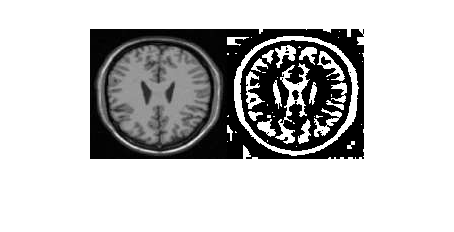

BW_img_global=imbinarize(img,'global');
figure(1)
imshowpair(img,BW_img_global,'montage')

figure(2)
imshowpair(BW_img,BW_img_global,'montage')

Unrecognized function or variable 'BW_img_global'.

In this testing, some of details part of  the image might be discarded since there is only one global threshold inserted into the algorithm.

**Adaptive Threshold Computation Method:**

**Basic Idea:**

Adaptive method focuses on calculating the locally adaptive image threshold chosed using **local first-order image statistics around each pixel.**

**Typical First order image statistical features:**

- **mean**

- **standard deviation**

- **skewness**

- **kortosis**

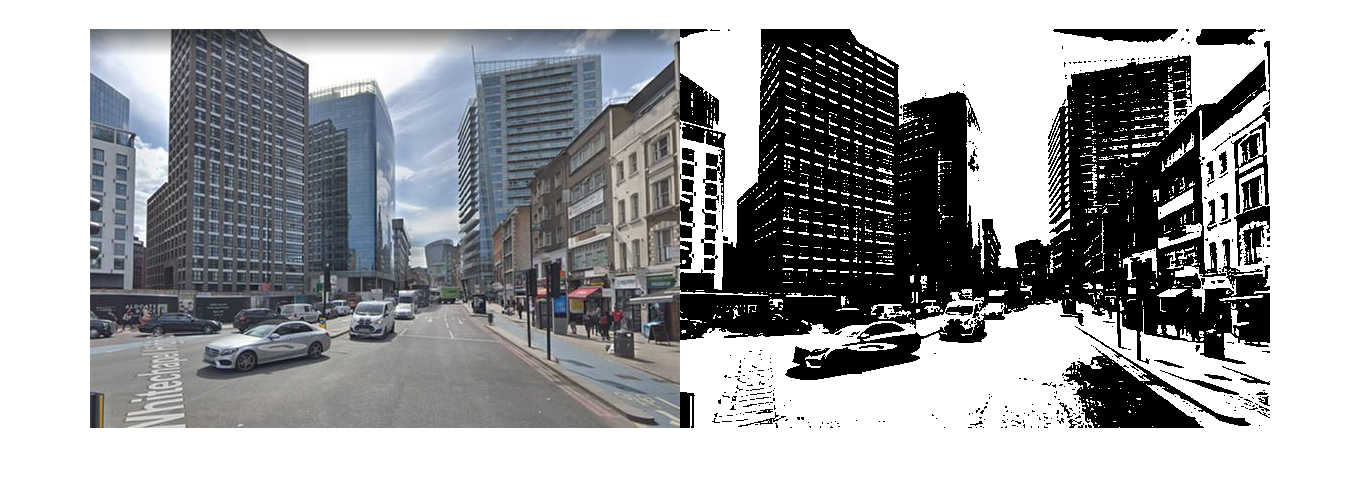

BW_img_adaptive=imbinarize(img,'adaptive');
figure(1)
imshowpair(img,BW_img_adaptive,'montage')
figure(2)

imshowpair(BW_img_global,BW_img_adaptive,'montage')

In this testing, some of the part of the brain is shown as black, which is resulted due to the mechanism of adaptivve method : calculating locally first order image statistics. As we performed image segmentation, this may result in wrong sorting.

**Testing with Multiple Color Object:**

**Image citation: Google map**

color_map=imread("google-maps-how-to-get-street-view-google-maps-2421144.jpg"); % read in sample color image
BW_map=rgb2gray(color_map); % convert it to grayscale
BW_map_global=imbinarize(BW_map); % conducting global thresholding
imshowpair(color_map,BW_map_global,'montage')

imshow(BW_map)

BW_map=rgb2gray(color_map); % convert it to grayscale
BW_map_adaptive=imbinarize(BW_map, 'adaptive'); % perfoem adaptive thresholding
imshowpair(BW_map_global,BW_map_adaptive,'montage')

From the above result, some of the region are sorted inappropriately. For example, the could part in the sky on the left and the shadow portion of the building on the left are blended into one region, which might cause problem in image segmentation. Therefore, thresholding method might not work well in a image which contains more complicated structures.

**Pros and Cons:**

**Pros:**

- Good for grayscale image, which has relative distinct mean in lightness intensity

- Good for separating binarized categories (like shadow and lightness)

**Cons:**

- Not easy to tell what category it is in each region (for example, in adaptive brain image, some brain region is shown as dark, which may be confused as shadow region)

- In global method, it has intention to lose the detial part of the image (for global grain image, some of the fold parts are eliminated)

- In adaptive method, it has intension to sort the regions into wrong categories (for adaptivve street image, the shadow part on the building and the cloud part in the sky) 